# Cinematica inversa del robot RRP polare

## Robot polare RRP

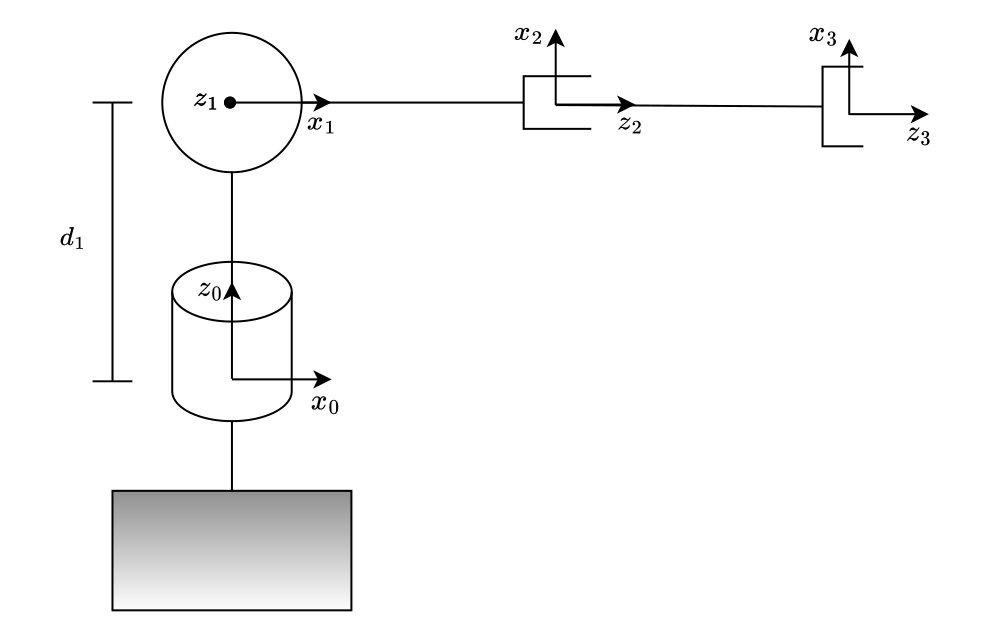

syms q1 q2 q3 d1 
DHRRPpolare = [0, pi/2, d1, q1; 
               0, pi/2, 0, q2+pi/2; 
               0, 0, q3, 0]

$$DHRRPpolare = \left(\begin{array}{cccc} 0 & \frac{\pi }{2} & d_{1} & q_{1}\\ 0 & \frac{\pi }{2} & 0 & q_{2}+\frac{\pi }{2}\\ 0 & 0 & q_{3} & 0 \end{array}\right)$$

tList = cinDirDH(DHRRPpolare);
T03 = tList{4}

$$T03 = \left(\begin{array}{cccc} -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & \sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & q_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ -\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & -\cos\left(q_{1}\right) & \cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & q_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ \cos\left(q_{2}\right) & 0 & \sin\left(q_{2}\right) & d_{1}+q_{3}\,\sin\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

r = T03(1:3, 4)

$$r = \left(\begin{array}{c} q_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ q_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ d_{1}+q_{3}\,\sin\left(q_{2}\right) \end{array}\right)$$

Jr = jacobian(r, [q1, q2, q3])

$$Jr = \left(\begin{array}{ccc} -q_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & -q_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ q_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -q_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & \cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ 0 & q_{3}\,\cos\left(q_{2}\right) & \sin\left(q_{2}\right) \end{array}\right)$$

Jr.'

$$ans = \left(\begin{array}{ccc} -q_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & q_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & 0\\ -q_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & -q_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & q_{3}\,\cos\left(q_{2}\right)\\ \cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & \cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \sin\left(q_{2}\right) \end{array}\right)$$

## Cinematica inversa analitica

P = [1; 1; 1];
d_1 = 0.5;
q_an = cinInvAnaliticaRRPpolare(P, d_1)

q_an =     0.7854
    0.3398
    1.5000


round(subs(r, [q1, q2, q3, d1], [q_an(1), q_an(2), q_an(3), d_1]), 10)

$$ans = \left(\begin{array}{c} 1.0\\ 1.0\\ 1.0 \end{array}\right)$$

## Cinematica inversa numerica

qi = [1; 0.4; 0];
q_num = cinInvNumericaRRPpolare(P, d_1, qi)

q_num =     0.7854
    0.3398
    1.5000


round(subs(r, [q1, q2, q3, d1], [q_num(1), q_num(2), q_num(3), d_1]), 10)

$$ans = \left(\begin{array}{c} 0.9999999946\\ 0.9999999946\\ 0.9999999973 \end{array}\right)$$

errore = round(norm(q_an - q_num), 10)

errore = 8.1000e-09